# Import AUTOSAR Composition into Architecture Model

Import ARXML description of AUTOSAR software composition into architecture model.

After you create an AUTOSAR architecture model (requires System Composer), develop the top-level AUTOSAR software design. The composition editor provides a view of AUTOSAR software architecture based on the AUTOSAR Virtual Function Bus (VFB).

## **Import AUTOSAR Composition from ARXML File**

If you have an ARXML description of an AUTOSAR software composition, you can import the composition into an AUTOSAR architecture model. The import creates a Simulink representation of the composition at the top level of the architecture model. Composition import requires an open AUTOSAR architecture model with no functional content.

To import an AUTOSAR software composition from ARXML files into an architecture model:

1. Create or open an AUTOSAR architecture model that has no functional content. For example, enter this MATLAB® command.

% Create AUTOSAR architecture model
modelName = "myArchModel";
archModel = autosar.arch.createModel(modelName);

2. In the open architecture model, on the **Modeling** tab, in the **Component** menu, select **Import from ARXML**.

3. In the AUTOSAR Importer app, in the **Select ARXML** pane, in the **ARXML Files** field, enter the names of one or more ARXML files (comma separated) that describe an AUTOSAR software composition. For this example, enter `ThrottlePositionControlComposition.arxml`.

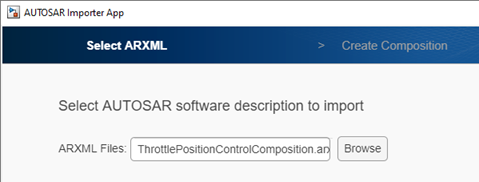

Click **Next**. The app parses the specified ARXML file.

4. In the **Create Composition** pane, the **Composition name** menu lists the compositions found in the parsed ARXML file. Select the composition `/Company/Components/ThrottlePositionControlComposition`.

Optionally, to view additional modeling options for composition creation, select **Configure Modeling Options**.

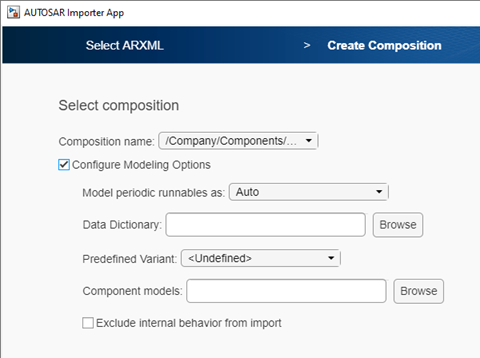

You can specify:

- Whether to include or exclude AUTOSAR software components, which define composition behavior. By default, the import includes components within the composition.

- Simulink data dictionary in which to place data objects for imported AUTOSAR data types.

- Names of existing Simulink behavior models to link to imported AUTOSAR software components.

- Component options to apply when creating Simulink behavior models for imported AUTOSAR software components. For example, how to model periodic runnables, or a `PredefinedVariant` or `SwSystemconstantValueSet`s with which to resolve component variation points.

For more information about modeling options and behavior, see the [`importFromARXML`](docid:autosar_ref.mw_03b8eba2-ac5f-480d-83d4-b7acd6a608a4) reference page.

5. To finish importing the composition into the architecture model, click **Finish**. The Diagnostic Viewer displays the progress of the composition creation. On completion, the imported composition appears in the software architecture canvas.

To perform steps 2 through 5 programmatically, run these commands.

% Import composition from file ThrottlePositionControlComposition.arxml
importerObj = arxml.importer("ThrottlePositionControlComposition.arxml");  % Parse ARXML
importFromARXML(archModel,importerObj,...
  "/Company/Components/ThrottlePositionControlComposition");

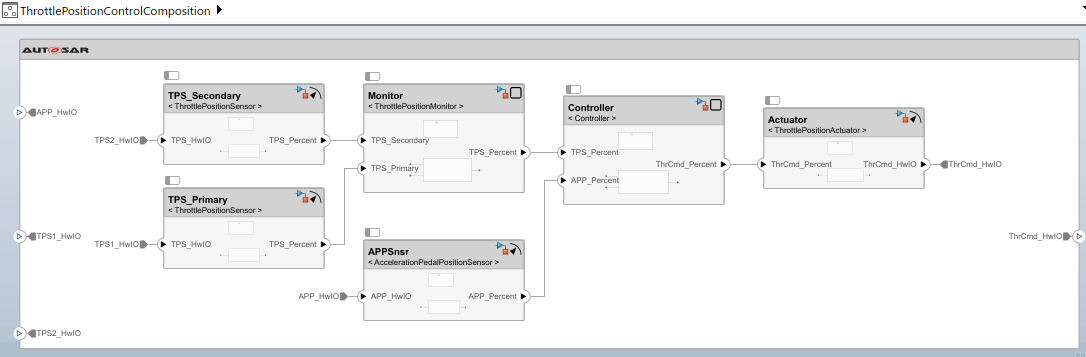

Because this composition import was configured to include AUTOSAR software components (modeling option **Exclude internal behavior from import** was cleared), the import created Simulink models for each component in the composition.

## **Develop AUTOSAR Component Algorithms**

After creating an initial Simulink representation of the AUTOSAR composition, you develop each component in the composition. For each component, you refine the AUTOSAR configuration and create algorithmic model content.

For example, the `Controller` component model in the `ThrottlePositionControlComposition` composition model contains an atomic subsystem `Runnable_Step_sys`, which represents an AUTOSAR periodic runnable. The `Runnable_Step_sys` subsystem contains the initial stub implementation of the controller behavior.

Here is a possible implementation of the throttle position controller behavior. (To explore this implementation, see the model `autosar_swc_controller`, which is provided with the example [Design AUTOSAR Components, Simulate, and Generate Code](docid:autosar_ug.mw_2cca1e20-3bca-4a1a-b954-8021e1cc3c51).) The component takes as inputs an APP sensor percent value from a pedal position sensor and a TPS percent value from a throttle position sensor. Based on these values, the controller calculates the *error*. The error is the difference between where the operator wants the throttle, based on the pedal sensor, and the current throttle position. In this implementation, a Discrete PID Controller block uses the error value to calculate a throttle command percent value to provide to a throttle actuator. A scope displays the error value and the Discrete PID Controller block output value over time.

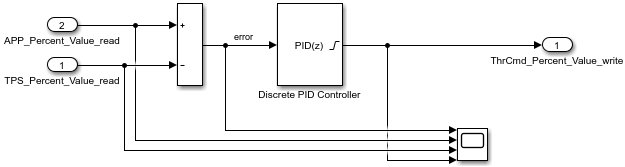

As you develop AUTOSAR components, you can:

- Simulate component models individually or as a group within the architecture model.

- Generate ARXML description files and algorithmic C code for testing in Simulink or integration into an AUTOSAR run-time environment. (AUTOSAR code generation requires Simulink Coder and Embedded Coder.)

For more information on developing, simulating, and building AUTOSAR components, see example [Design AUTOSAR Components, Simulate, and Generate Code](docid:autosar_ug.mw_2cca1e20-3bca-4a1a-b954-8021e1cc3c51).

## Related Links

- [`importFromARXML`](docid:autosar_ref.mw_03b8eba2-ac5f-480d-83d4-b7acd6a608a4)

- [Import AUTOSAR Composition from ARXML](docid:autosar_ug.mw_e3d84f62-6a90-493f-92a2-ee82557a0b78)

- [Author AUTOSAR Compositions and Components in Architecture Model](docid:autosar_ug.mw_86f1737b-0186-4dd8-a280-717bf9420c3f)

- [Design AUTOSAR Components, Simulate, and Generate Code](docid:autosar_ug.mw_2cca1e20-3bca-4a1a-b954-8021e1cc3c51)

*Copyright 2020 The MathWorks, Inc.*